# Part 1: Dilation

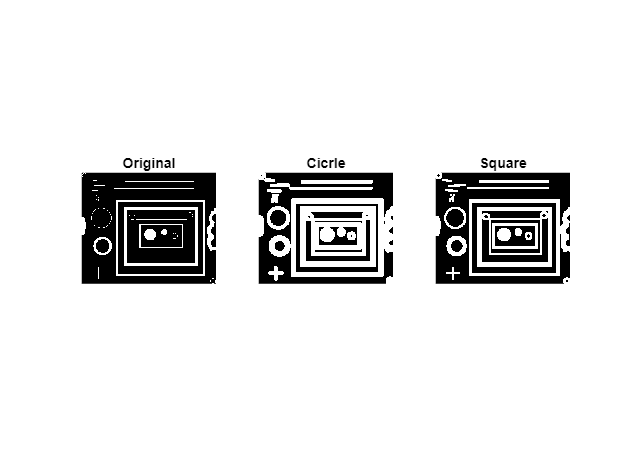

% 1. Blobs dilation
% Read images
blobs = imread("blobs.png");
% Initialise SE values for dilation
se1 = strel('disk', 5);
se2 = strel('square', 5);
se3 = strel('square', 2);
se4 = strel('line', 2, 90);
% Apply dilations to image
square_circle_1 = imdilate(blobs, se1);
square_circle_2 = imdilate(blobs, se2);
% Plot the images
figure;
subplot(131);
imshow(blobs);
title('Original');
subplot(132);
imshow(square_circle_1);
title('Cicrle');
subplot(133);
imshow(square_circle_2);
title('Square');

% Save the images
%{
imwrite(square_circle_1, "square-circle-1.png");
imwrite(square_circle_2, "square-circle-2.png");
%}

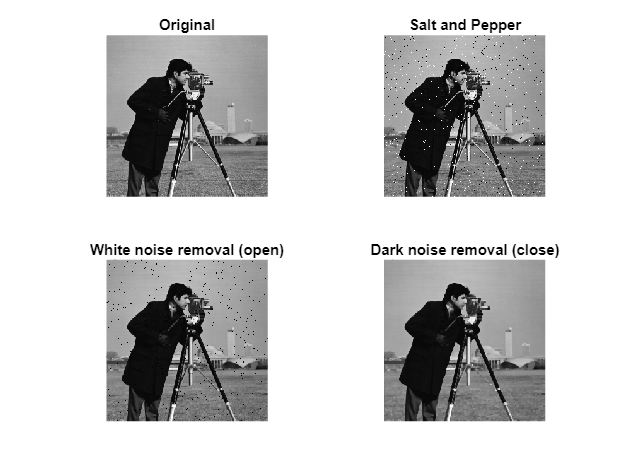

% 2. Dilation & Noise reduction
% Read image
camera = imread("cameraman.tif");
% Add Salt and Pepper to camera
camera_sp = imnoise(camera, "salt & pepper", 0.02);
% Dilate and Remove noise in the image
cam_d = imopen(camera_sp, se3); % get rid of white noise
cam_nr = imclose(cam_d, se3); % get rid of black noise
% Plot the images
figure;
subplot(221);
imshow(camera);
title('Original');
subplot(222);
imshow(camera_sp);
title('Salt and Pepper');
subplot(223);
imshow(cam_d);
title('White noise removal (open)');
subplot(224);
imshow(cam_nr);
title('Dark noise removal (close)');

% Save image
%{
imwrite(cam_nr, "cameraman-denoised.png");
%}

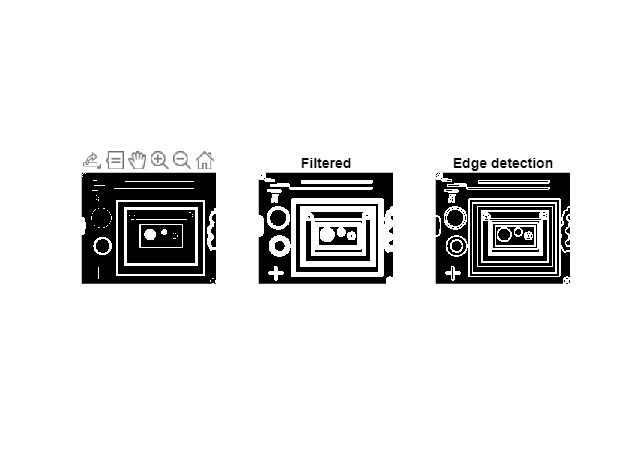

% 3. Edge Detection
% Edge detection calculation: edge = filtered - original
% Read images
lena_original = imread("Lena-2.tif");
kranen_original = imread("kranen.tif");
% a. Blobs image
blob_edge = square_circle_1 - blobs;
% Plot blob images to compare
figure;
subplot(131);
imshow(blobs);
title('Original');
subplot(132);
imshow(square_circle_1);
title('Filtered');
subplot(133); 
imshow(blob_edge);
title('Edge detection');

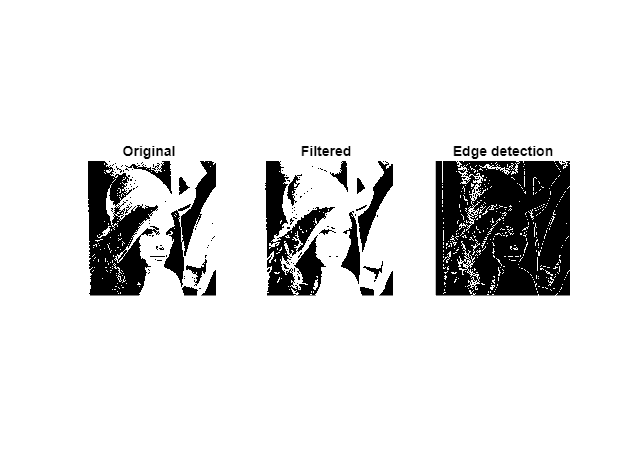

% b. Lena
% Convert grayscale and binarize the image
lena_gs = im2gray(lena_original);
level = 0.37;
lena_bw = imbinarize(lena_gs, level);
% Lena filter
lena_fil = strel('disk', 2);
% Apply dilation on lena image
lena_dil = imdilate(lena_bw, lena_fil);
% Edge for lena
lena_edge = lena_dil - lena_bw;
% Plot the images for comparison
figure;
subplot(131);
imshow(lena_bw);
title('Original');
subplot(132);
imshow(lena_dil);
title('Filtered');
subplot(133);
imshow(lena_edge);
title('Edge detection');

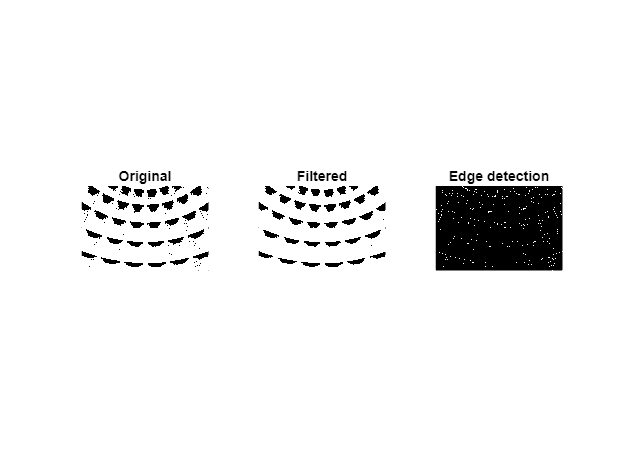

% c. Kranen
% Convert grayscale and binarize the image
kranen_gs = im2gray(kranen_original);
level2 = 0.30;
kranen_bw = imbinarize(kranen_gs, level2);
% Apply filter on kranen image
kranen_dil4 = imdilate(kranen_bw, se1); % disk = 5
% Edge detection
k4 = kranen_dil4 - kranen_bw;
% Plot images for comparison
figure;
subplot(131)
imshow(kranen_bw);
title('Original');
subplot(132);
imshow(kranen_dil4);
title('Filtered')
subplot(133);
imshow(k4);
title('Edge detection');

## Part 2: Erosion

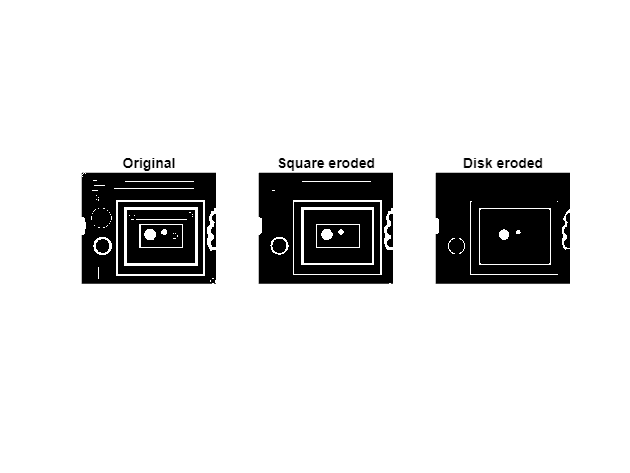

% 1. Erosion technique
se5 = strel('disk', 2);
% Apply the filter <3
blob_erosion_d = imerode(blobs, se3); % square 2
blob_erosion_s = imerode(blobs, se5); % disk 2
% Plot the images
figure;
subplot(131);
imshow(blobs);
title('Original');
subplot(132);
imshow(blob_erosion_d);
title('Square eroded')
subplot(133);
imshow(blob_erosion_s);
title('Disk eroded');

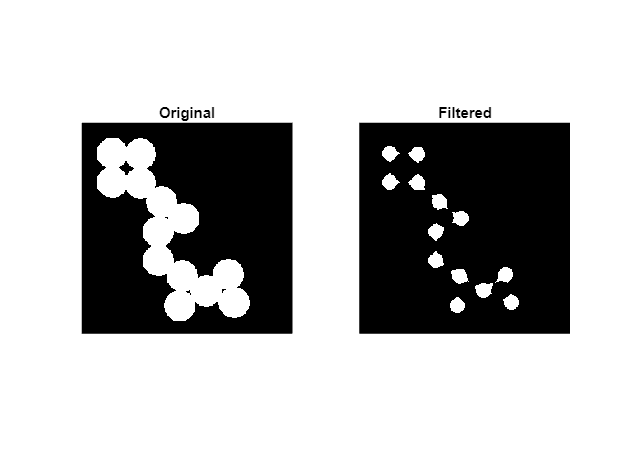

% 2. Circle image
circle = imread('circles.png');
% Filter
se6 = strel('sphere', 10);
% Apply filter
circle_errosion = imerode(circle, se6);
% Plot the images
figure;
subplot(121);
imshow(circle);
title('Original');
subplot(122);
imshow(circle_errosion);
title('Filtered');

## Part 3: Opening and Closing

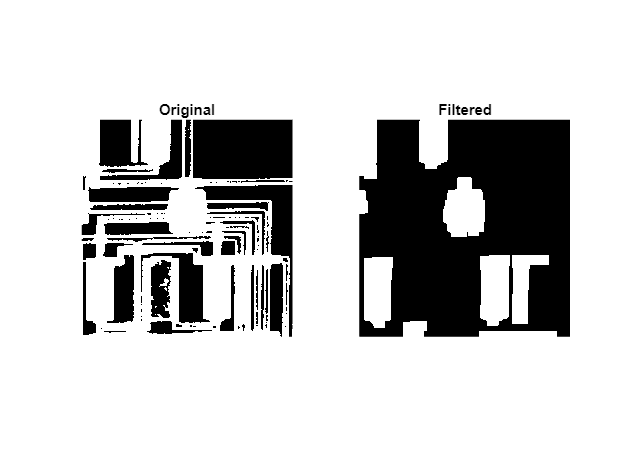

% Image
circbw = imread('circbw.tif');
se7 = strel('square', 14);
% Filter
circ1 = imopen(circbw, se7);
% Plot images
figure;
subplot(121);
imshow(circbw);
title('Original');
subplot(122);
imshow(circ1);
title('Filtered');

## Part 4: Skeletonization

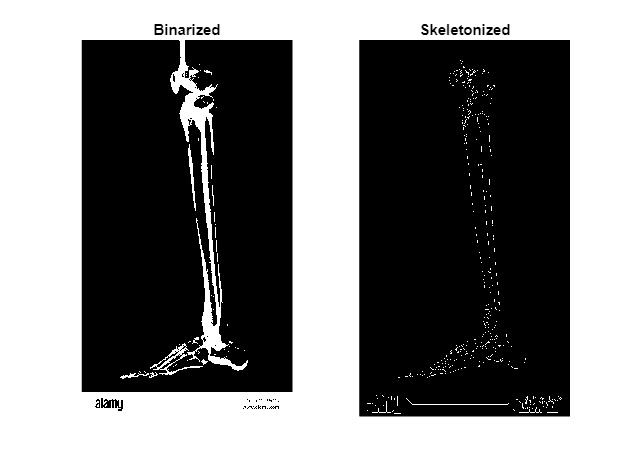

% Leg image processing
leg = imread('ower-leg.tif');
leg_gs = rgb2gray(leg);
level3 = 0.72;
leg_bi = imbinarize(leg_gs, level3);
leg_complement = imcomplement(leg_bi);
leg_skeleton = bwskel(leg_complement);
% Plot the images
figure;
subplot(121);
imshow(leg_complement);
title('Binarized');
subplot(122);
imshow(leg_skeleton);
title('Skeletonized');

## Part 5: Additional Task

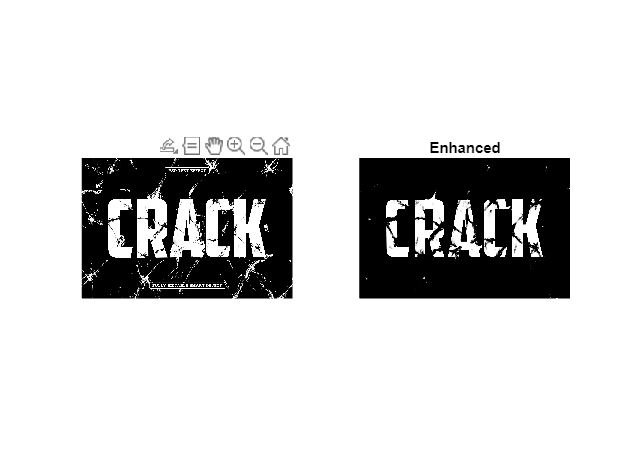

% 1. Crack image enhancement
crack = imread('cracked.tif');
se8 = strel('disk', 13);
crack_fil = imerode(crack, se8);
figure;
subplot(121);
imshow(crack);
title('Original');
subplot(122);
imshow(crack_fil);
title('Enhanced');

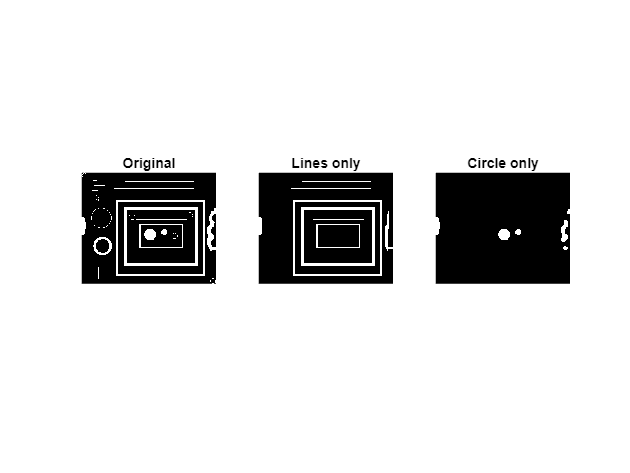

% 2. Separate lines and circles from blob, generate 2 images
% of only lines and circles
blobs = imread('blobs.png');
% Filters
h_line = strel("line", 30, 0);
v_line = strel("line", 30, 90);
% Circle only image
circ_only = imopen(blobs, se1);
% Lines only image
h_line_img = imopen(blobs, h_line);
v_line_img = imopen(blobs, v_line);
lines_only = h_line_img + v_line_img;
% Plot the images
figure;
subplot(131);
imshow(blobs);
title('Original');
subplot(132);
imshow(lines_only);
title('Lines only');
subplot(133);
imshow(circ_only);
title('Circle only');